clear all
clc 
close all
% Add paths to ToolboxLS and helperOC
addpath(genpath('C:\Users\saber\OneDrive\Desktop\Research\Pablo-Marek-Begum\Weekly Meeting\New folder\ToolboxLS'));
addpath(genpath('C:\Users\saber\OneDrive\Desktop\Research\Pablo-Marek-Begum\Weekly Meeting\New folder\helperOC-master'));

#### H`elperOC` toolbox

Create the grid

theta_max=0.3;
theta_dot_max=0.6;
mins = [-theta_max; -theta_dot_max]; % Minimum values for each dimension
maxs = [theta_max; theta_dot_max]; % Maximum values for each dimension
nums = [101; 201]; % Number of grid points in each dimension

% Create the grid
g = createGrid(mins, maxs, nums);

###  Define target function.

data0 = shapeRectangleByCorners(g, [-theta_max, -theta_dot_max], [theta_max, theta_dot_max]);
HJIextraArgs.targetFunction = data0;

### Plot target function.

figure(1);
subplot(1, 2, 1);
visFuncIm(g, data0, 0.5);
hold on;
grid on;
axis equal;
subplot(1, 2, 2);
visSetIm(g, data0, 'r', 0); 
hold on;
axis equal;
grid on;
xticks(-1:1:1);

#### Time vector

t0 = 0;
tMax = 2.5;
dt = 0.01;
tau = t0:dt:tMax;

#### Min or Max

uMode = 'min';
schemeData.uMode = uMode;
% backward or forward?
schemeData.tMode = 'backward';

#### Define dynamical system

params.l=1;    % [m]        length of pendulum
params.m=2;    % [kg]       mass of pendulum
params.g=9.81; % [m/s^2]    acceleration of gravity
params.b=0; % [s*Nm/rad] friction coefficient
params.u_min=-3;
params.u_max=3;
x0=[0.1;0];
boat = InvertedPendulum(x0,params);
% Put grid and dynamic systems into schemeData
schemeData.grid = g;
schemeData.dynSys = boat;


#### Set accuracy

schemeData.accuracy = 'high'; 

#### Compute value function

HJIextraArgs.visualize.valueSet = 1;
HJIextraArgs.visualize.initialValueSet = 1;
HJIextraArgs.visualize.figNum = 2; %set figure number
HJIextraArgs.visualize.deleteLastPlot = true; %delete previous plot as you update


#### For set computation, use 'none'. For tube computation, use 'minVWithL'

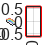

tau(i) = 0.010000
  Computing [0.000000 0.010000]...
  Computing [0.000960 0.010000]...
  Computing [0.001920 0.010000]...
  Computing [0.002881 0.010000]...
  Computing [0.003841 0.010000]...
  Computing [0.004801 0.010000]...
  Computing [0.005761 0.010000]...
  Computing [0.006721 0.010000]...
  Computing [0.007681 0.010000]...
  Computing [0.008642 0.010000]...
  Computing [0.009602 0.010000]...
tau(i) = 0.020000
  Computing [0.010000 0.020000]...
  Computing [0.010960 0.020000]...
  Computing [0.011920 0.020000]...
  Computing [0.012881 0.020000]...
  Computing [0.013841 0.020000]...
  Computing [0.014801 0.020000]...
  Computing [0.015761 0.020000]...
  Computing [0.016721 0.020000]...
  Computing [0.017681 0.020000]...
  Computing [0.018642 0.020000]...
  Computing [0.019602 0.020000]...
tau(i) = 0.030000
  Computing [0.020000 0.030000]...
  Computing [0.020960 0.030000]...
  Computing [0.021920 0.030000]...
  Computing [0.022881 0.030000]...
  Computing [0.023841 0.030000]...
 

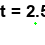

Total execution time 140.641 seconds


compMethod = 'none';
[data, tau2, ~] = ...
  HJIPDE_solve(data0, tau, schemeData, compMethod, HJIextraArgs);

#### Plot the final time target function.

figure(1);
subplot(1, 2, 1);
hold on;
visFuncIm(g, squeeze(data(:, :, end)), 0.5);
subplot(1, 2, 2);
hold on;
visSetIm(g, squeeze(data(:, :, end)), 'b', 0);

#### Compute optimal trajectory from some initial state

% set the initial state
xinit = [0.1; 0];
boat.x = xinit; %set initial state of the dubins car
% set if control wants to min or max
TrajextraArgs.uMode = uMode; 
% flip data time points so we start from the beginning of time
dataTraj = flip(data,3);
[traj, traj_tau] = ...
      computeOptTraj(g, dataTraj, tau2, boat, TrajextraArgs);

#### Showing trajectory.

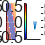

figure(1);
subplot(1, 2, 2);
plot(traj(1, :), traj(2, :));

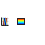

% Assuming g is your grid and data is your data array

% Plot the desired surface
figure;
surf(g.xs{1}, g.xs{2}, data(:,:,25), 'EdgeColor', 'none'); % Create a surface plot with no edges
colormap jet; % Use a jet colormap for better color differentiation
colorbar; % Add a colorbar to indicate the height

% Adjust the view to top-down view
view(2); % This sets the view to a 2D view from the top

hold on;
grid on;
axis equal;

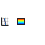

% Assuming g is your grid and data is your data array

% Define the threshold for the dark blue color (you may need to adjust this value)
threshold = -0.2;

% Create a mask for the data points below the threshold
mask = data(:,:,25) < threshold;

% Apply the mask to the data
dataMasked = data(:,:,25);
dataMasked(~mask) = NaN; % Set values above the threshold to NaN

% Plot the desired surface
figure;
surf(g.xs{1}, g.xs{2}, dataMasked, 'EdgeColor', 'none'); % Create a surface plot with no edges
colormap jet; % Use a jet colormap for better color differentiation
colorbar; % Add a colorbar to indicate the height

% Adjust the view to top-down view
view(2); % This sets the view to a 2D view from the top

hold on;
grid on;
axis equal;

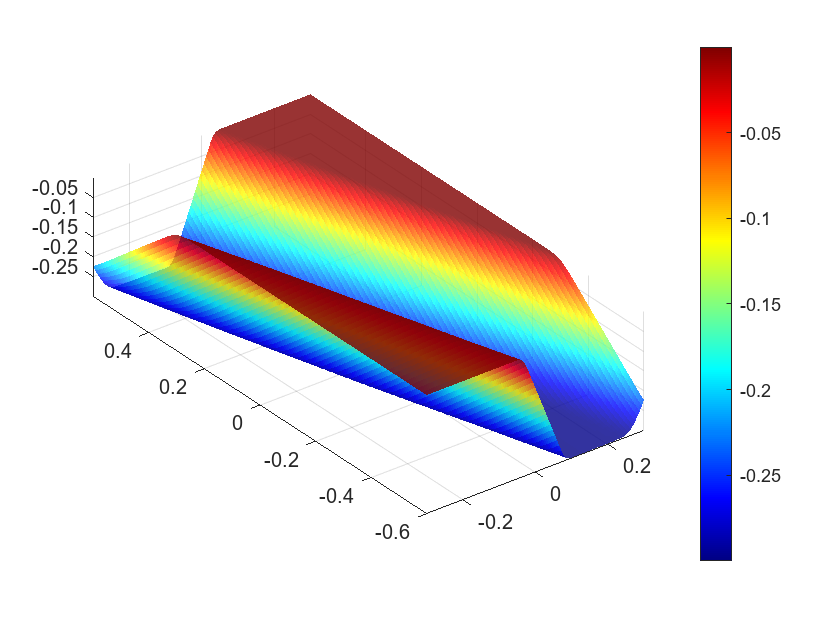

% Assuming g is your grid and data is your data array
data_dime = size(data);

% Create a figure for the animation
figure;

% Initialize the plot with the first time step
h = visFuncIm(g, data(:,:,1),0.1);
hold on;
grid on;
axis equal;

% Loop through each time step to update the plot
for time_step = 1:data_dime(3)
    % Update the plot with the current time step data
    delete(h); % Remove the previous plot
    h = visFuncIm(g, data(:,:,time_step), 0.8); % Plot the new data
    
    % Update the figure window
    drawnow;
end


% Ensure the final frame is visible
set(h, 'CData', data(:,:,end));
drawnow;